fs = 44100; %sampling rate
%f0 = 220; %desired fundamental
%M = round(f/f0); %number of delay samples
%A = [1 zeros(1, M-1)];
g = 1; %feedback gain
a = 1;
b = [1 zeros(1, 126) g];
%freqz(B, A);
[h,w] = freqz(b,a,1024);
f = (w/(2*pi))*fs;

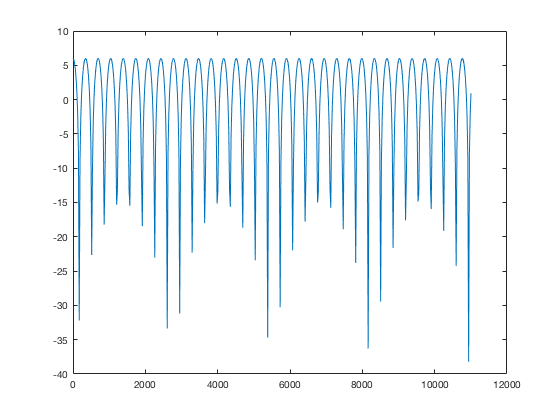

f_ = f(1:length(f)/2);
h_ = h(1:length(h)/2);
plot(f_,20*log10(abs(h_)));

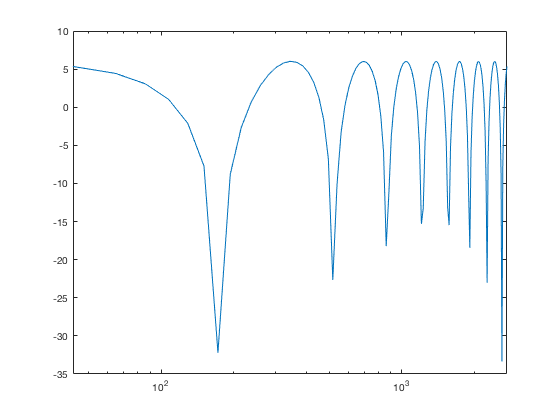


f_ = f_(3:length(f)/8);
h_ = h_(3:length(h)/8);
plot(f_,20*log10(abs(h_)));
%set(gca, 'XScale', 'log');

%plot(10*log10(f),20*log10(abs(h)))

%plot(10*log((w/(2*pi))*fs),20*log10(abs(h)))

%[h,f] = freqz(b,a,1024,'whole',44100);
%plot(10*log(f),20*log10(abs(h)))
%[h,f] = freqz(B,A,44100);
%plot(10*log(f*44100),20*log10(abs(h)))

% ax = gca;
% ax.YLim = [-100 20];
% ax.XTick* = 0:.5:2;
% xlabel('Normalized Frequency (\times\pi rad/sample)')
% ylabel('Magnitude (dB)')